# RVC2: Chapter 7

format compact
close all
clear
clc

## 7.1.1  Planar (2D) robotic arms

import ETS2.*

右乘 理解

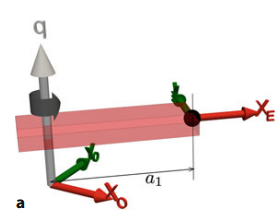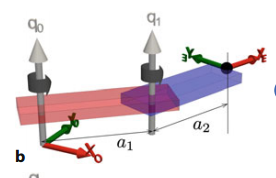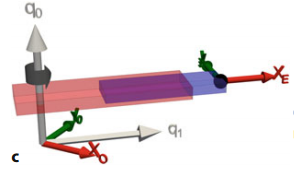

a1 = 1;
E = Rz('q1') * Tx(a1)

E = 
Rz(q1)Tx(1)


E.fkine( 30, 'deg')

ans = 
    0.8660   -0.5000     0.866
    0.5000    0.8660       0.5
         0         0         1


creating new ETS plot


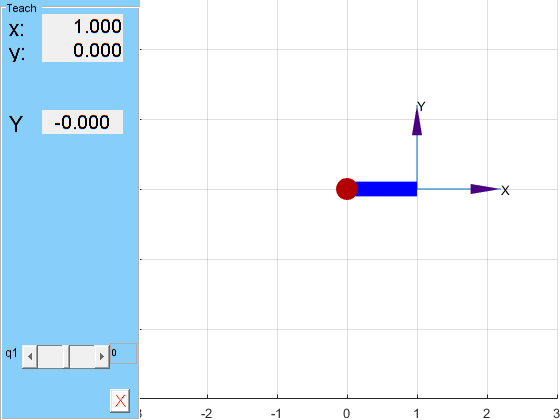

E.teach


a1 = 1; a2 = 1;
E = Rz('q1') * Tx(a1) * Rz('q2') * Tx(a2)

E = 
Rz(q1)Tx(1)Rz(q2)Tx(1)


E.fkine( [30, 40], 'deg')

ans = 
    0.3420   -0.9397     1.208
    0.9397    0.3420      1.44
         0         0         1


creating new ETS plot


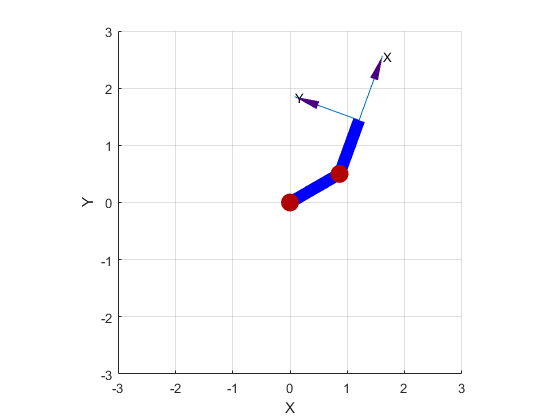

E.plot( [30, 40], 'deg')

E.structure

ans = 'RR'

a1 = 1;
E = Rz('q1') * Tx(a1) * Tx('q2')

E = 
Rz(q1)Tx(1)Tx(q2)


E.structure

ans = 'RP'

## 7.1.2  3-dimensional robotic arms

These commands need to be executed manually in the command window, then continue

clear all

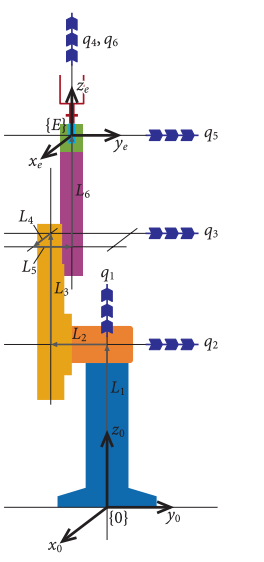

import ETS3.*
L1 = 0; L2 = -0.2337; L3 = 0.4318; L4 = 0.0203; L5 = 0.0837; L6 = 0.4318;
E3 = Tz(L1) * Rz('q1') * Ry('q2') * Ty(L2) * Tz(L3) * Ry('q3') ...
* Tx(L4) * Ty(L5) * Tz(L6) * Rz('q4') * Ry('q5') * Rz('q6')

E3 = 
 Tz(0) Rz(q1) Ry(q2) Ty(-0.2337) Tz(0.4318) Ry(q3) Tx(0.0203) Ty(0.0837) Tz(0.4318) Rz(q4) Ry(q5) Rz(q6)



E3.fkine([0 0 0 0 0 0])

ans = 
         1         0         0    0.0203
         0         1         0     -0.15
         0         0         1    0.8636
         0         0         0         1


## 7.1.2.1 Denavit-Hartenberg parameters

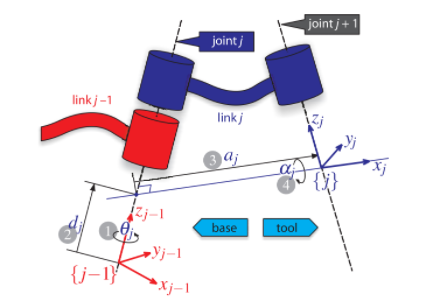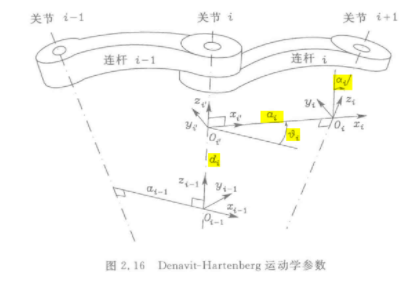

  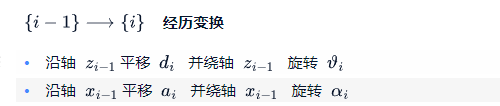

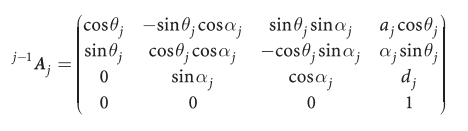

L = Revolute('a', 1)  % theta=q, d=0, a=1, alpha=0, offset=0

L = 
Revolute(std): theta=q, d=0, a=1, alpha=0, offset=0


L.A(0.5) % q = 0.5

ans = 
    0.8776   -0.4794         0    0.8776
    0.4794    0.8776         0    0.4794
         0         0         1         0
         0         0         0         1


L.type

ans = 'R'

L.a

ans = 1

offset 是针对关节变量   关节坐标偏移量 提供了为**零关节坐标情况**设置任意配置的机制。

L.offset = 0.5;
L.A(0)

ans = 
    0.8776   -0.4794         0    0.8776
    0.4794    0.8776         0    0.4794
         0         0         1         0
         0         0         0         1


robot = SerialLink( [ Revolute('a', 1) Revolute('a', 1) ], ...
'name', 'my robot')

robot = 
my robot:: 2 axis, RR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+



robot.fkine([30 40], 'deg')

ans = 
   -0.4453   -0.8954         0    -1.358
    0.8954   -0.4453         0    0.4856
         0         0         1         0
         0         0         0         1


robot.edit
pause(5)
close all



机器人预定好的模型


models

ABB, IRB140, 6DOF, modified_DH (mdl_irb140_mdh)
ABB, IRB140, 6DOF, standard_DH (mdl_irb140)
ABB, S4_2.8, S4 2.8m reach version, 6DOF, standard_DH (mdl_S4ABB2p8)
Adept, Cobra600, 4DOF, standard_DH (mdl_cobra600)
Aldebaran, NAO, humanoid, 4DOF, standard_DH (mdl_nao)
Baxter, Rethink Robotics, 7DOF, standard_DH (mdl_baxter)
Fanuc, AM120iB/10L, 6DOF, standard_DH (mdl_fanuc10L)
Fanuc, M16, 6DOF, standard_DH (mdl_M16)
Franka-Emika, PANDA, 7DOF, standard_DH (mdl_panda)
Kinova, Jaco, 6DOF, standard_DH (mdl_jaco)
Kinova, Mico, 6DOF, standard_DH (mdl_mico)
Kuka, KR5, 6DOF, standard_DH (mdl_KR5)
Kuka, LWR, 7DOF, standard_DH (mdl_LWR)
Motoman, HP6, 6DOF, standard_DH (mdl_motomanHP6)
Rethink Robotics, Sawyer, 7DOF, standard_DH (mdl_sawyer)
Stanford, Stanford Arm, prismatic, 6DOF, standard_DH (mdl_stanford)
Stanford, Stanford arm, prismatic, 6DOF, modified_DH (mdl_stanford_mdh)
Trossen Robotics, PhantomX Pincher, 4DOF, standard_DH (mdl_phantomx)
Unimation, Puma560, dynamics, 6DOF, modified_DH (mdl_pu

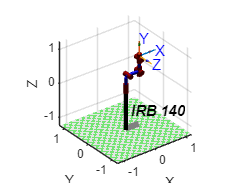

mdl_irb140
% qr qz qd 预定义的 关节角
irb140.plot(qz)

## 7.1.2.2 Product of exponentials

a1 = 1; a2 = 1;
TE0 = SE2(a1+a2, 0, 0); 

S1 = Twist( 'R', [0 0] );
S2 = Twist( 'R', [a1 0] );

TE = S1.T(30, 'deg') * S2.T(40, 'deg') * TE0.T % TE0.T  齐次矩阵

TE =     0.3420   -0.9397    1.2080
    0.9397    0.3420    1.4397
         0         0    1.0000


## 7.1.2.3 6-axis industrial robot

mdl_puma560
p560

p560 = 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+


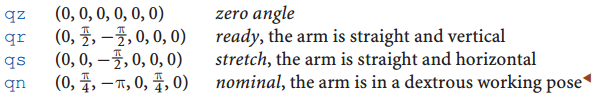    

% qz  Zero angle
TE = p560.fkine(qz)

TE = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1


p560.plot(qz)

    设置工具      fkine 返回 tcp 位姿

p560.tool = SE3(0, 0, 0.2);
p560.fkine(qz)

ans = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.6318
         0         0         0         1


p560.plot(qz)

    设置Base

p560.base = SE3(0, 0, 30*0.0254);
p560.fkine(qz)

ans = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1     1.394
         0         0         0         1



p560.base = SE3(0,0,3) * SE3.Rx(pi);
p560.fkine(qz)

ans = 
         1         0         0    0.4521
         0        -1         0      0.15
         0         0        -1     2.368
         0         0         0         1


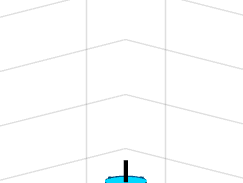

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


p560.plot3d(qz)

jtraj 关节角 轨迹的插值

q=jtraj(qz, qr, 8);  % 8 行（样本） * 6 
q

q =          0         0         0         0         0         0
         0    0.0365   -0.0365         0         0         0
         0    0.2273   -0.2273         0         0         0
         0    0.5779   -0.5779         0         0         0
         0    0.9929   -0.9929         0         0         0
         0    1.3435   -1.3435         0         0         0
         0    1.5343   -1.5343         0         0         0
         0    1.5708   -1.5708         0         0         0



T = p560.fkine(q);
about(T)

T [SE3] : 1x8 (1.0 kB)



T(4)

ans = 
         1         0         0     0.382
         0        -1         0      0.15
         0         0        -1     2.132
         0         0         0         1


## 7.2  Inverse kinematics

## 7.2.1.1  Closed-form solution

解析解  or 封闭解

clear all

import ETS2.*
a1 = 1; a2 = 1;
E = Rz('q1') * Tx(a1) * Rz('q2') * Tx(a2)

E = 
Rz(q1)Tx(1)Rz(q2)Tx(1)



%  forward kinematics 
syms q1 q2 real
TE = E.fkine( [q1, q2] )

$$\left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$


%  end-effector  position   
syms x y real
e1 = x == TE.t(1)  % e1 将是一个逻辑表达式，表示 x 和 TE.t(1) 相等的条件

$$e1 = x=\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)$$

e2 = y == TE.t(2)

$$e2 = y=\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)$$


% [e1 e2]  逻辑表达式成立时   变量[q1 q2] 的解[s1,s2]
[s1,s2] = solve( [e1 e2], [q1 q2] )

$$s1 = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{2\,y+\sigma_{2}+\sigma_{1}}{x^{2}+2\,x+y^{2}}\right)\\ -2\,\mathrm{atan}\left(\frac{\sigma_{2}-2\,y+\sigma_{1}}{x^{2}+2\,x+y^{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{y^{2}\,\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\\ \sigma_{2}=\frac{x^{2}\,\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}} \end{array}$$

$$s2 = \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right)\\ 2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right) \end{array}\right)$$


% 说明  有2组 解
length(s2) % 2

ans = 2

s2(1)

$$ans = -2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right)$$

## 7.2.1.2  Numerical solution

If the next block throws an error, go to the console and type clear import; import ETS2.*

% 多变量最小化函数 fminsearch
pstar = [0.6; 0.7];
% 初值 不一样 
% q = fminsearch( @(q) norm( E.fkine(q).t - pstar ), [3 5] )
q = fminsearch( @(q) norm( E.fkine(q).t - pstar ), [0 0] )

q =    -0.2295    2.1833



E.fkine(q).print

t = (0.6, 0.7), theta = 111.9 deg


creating new ETS plot


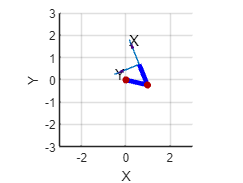

E.plot(q)

## 7.2.2  3-dimensional robot arms

## 7.2.2.1  Closed-form solution

mdl_puma560
qn

qn =          0    0.7854    3.1416         0    0.7854         0


T = p560.fkine(qn)

T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


qi = p560.ikine6s(T)

qi =     2.6486   -3.9270    0.0940    2.5326    0.9743    0.3734


T1= p560.fkine(qi)

T1 = 
         0         0         1    0.5963
         0         1         0     -0.15
        -1         0         0  -0.01435
         0         0         0         1


% p560.plot(qn)
% p560.plot(qi)


% left/right, up/down, noflip/flip 
% 八组关节坐标 解
qi = p560.ikine6s(T, 'ru')  

qi =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000


因为手臂不够长，无法达到这个姿势

p560.ikine6s( SE3(3, 0, 0) )

ans =    NaN   NaN   NaN   NaN   NaN   NaN


奇异点: q5 = 0   球形手腕  ：  Rz * Ry *  Rz      ==》  Rz  *  Rz  

q = [0 pi/4 pi 0.1 0 0.2];

p560.ikine6s(p560.fkine(q), 'ru')

ans =    -0.0000    0.7854    3.1416   -3.0409    0.0000   -2.9423



q(4)+q(6)

ans = 0.3000

## 7.2.2.2  Numerical solution

% qi  qn 不一致
T = p560.fkine(qn)
qi = p560.ikine(T)
qn

% T  p560.fkine(qi)一致
p560.fkine(qi)
p560.plot(qi) % elbow-down 
% 'q0', [0 0 3 0 0 0] 给定初始值
qi = p560.ikine(T, 'q0', [0 0 3 0 0 0])

## 7.2.2.3  Under-actuated manipulator

**欠驱动机械臂**

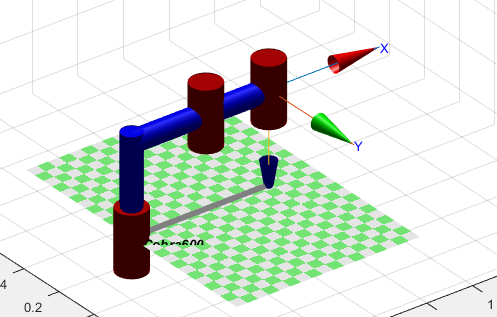

mdl_cobra600
c600 
% c600.plot(qz)

指定末端位姿, 这个位姿对四关节SCARA机器人来说是过度约束的,在物理上无法满足接近矢量的方向要求

要求在计算末端执行器位姿误差时不考虑绕x轴和y轴的旋转

T = SE3(0.4, -0.3, 0.2) * SE3.rpy(30, 40, 160, 'xyz', 'deg');
% 允许用户选择哪些自由度（平移或旋转）参与逆运动学求解
q = c600.ikine(T, 'mask', [1 1 1 0 0 1])  

Ta = c600.fkine(q);
Ta.print('xyz')

TT = c600.fkine(q);
clf
trplot(T, 'color', 'b')
hold on 
trplot(Ta, 'color', 'r')
hold off



## 7.2.2.4  Redundant manipulator

**冗余机械手**

引入约束： 一个常见的约束是**最小范数约束**

mdl_baxter


left
TE = SE3(0.8, 0.2, -0.2) * SE3.Ry(pi); 

q = left.ikine(TE)  % 最小范数的关节角向量

left.fkine(q).print('xyz')  



## 7.3  Trajectories

## 7.3.1  Joint-space motion

T1 = SE3(0.4, 0.2, 0) * SE3.Rx(pi);
T2 = SE3(0.4, -0.2, 0) * SE3.Rx(pi/2);

clf
trplot(T1, 'color', 'b')
hold on 
trplot(T2, 'color', 'r')
hold off

q1 = p560.ikine6s(T1);
q2 = p560.ikine6s(T2);

t = [0:0.05:2]';

q = mtraj(@tpoly, q1, q2, t); 
q = mtraj(@lspb, q1, q2, t);

**jtraj **

% 相当于带有tpoly插值的mtraj，
% 但针对多轴情况进行了优化，
% 还允许使用其他参数设置初始和最终速
q = jtraj(q1, q2, t);
[q,qd,qdd] = jtraj(q1, q2, t);
q = p560.jtraj(T1, T2, t)

序列 动画

clf
p560.plot(q)

角度与时间的关系

clf
plot(t, q(:,2))
qplot(t, q);

T = p560.fkine(q);
p = T.transl;
about(p)

plot(p(:,1), p(:,2))
plot(t, T.torpy('xyz'))

## 7.3.2  Cartesian motion

Ts = ctraj(T1, T2, length(t));
p = Ts.transl;
about(p)

plot3(p(:,1), p(:,2),p(:,3))
plot(t, Ts.torpy('xyz'))
plot(t, Ts.transl);


qc = p560.ikine6s(Ts);

## 7.3.3  Kinematics in Simulink

sl_jspace

## 7.3.4  Motion through a singularity

t≈0.7 s时，我们观察到手腕关节角度q4和q6的变化率变得非常高。原因是q5几乎变为零

T1 = SE3(0.5, 0.3, 0.44) * SE3.Ry(pi/2);
T2 = SE3(0.5, -0.3, 0.44) * SE3.Ry(pi/2);


通过 动画 以及 图看出  关节q4  q6 有突变 

Ts = ctraj(T1, T2, length(t));
qc = p560.ikine6s(Ts)
clf
qplot(t, qc);
% p560.plot(qc,'delay', 0.5)


使用 迭代解   就平稳  一直要求 关节角 最小范数

qd = p560.ikine(Ts)
clf
qplot(t, qd);


**可操纵性** : 即其在任何方向上轻松移动的能力，它是一个标量度量，越高越好，

mc = p560.maniplty(qc);
md = p560.maniplty(qd);
plot(t, mc,'color', 'b')
hold on
plot(t, md,'color', 'g')

## 7.3.5  Configuration change

因此**我们不能在笛卡尔空间中创建轨迹。相反，我们必须使用关节空间运动。**

T = SE3(0.4, 0.2, 0) * SE3.Rx(pi);

qr = p560.ikine6s(T, 'ru');
ql = p560.ikine6s(T, 'lu');

q = jtraj(qr, ql, t);

p560.plot(q)
qplot(t, q);


## 7.4.2  Determining DH params

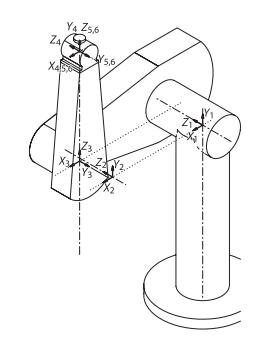

生成 DH 参数

s = 'Tz(L1) Rz(q1) Ry(q2) Ty(L2) Tz(L3) Ry(q3) Tx(L4) Ty(L5) Tz(L6) Rz(q4) Ry(q5) Rz(q6)'

s = 'Tz(L1) Rz(q1) Ry(q2) Ty(L2) Tz(L3) Ry(q3) Tx(L4) Ty(L5) Tz(L6) Rz(q4) Ry(q5) Rz(q6)'

dh = DHFactor(s);

INIT: Tz(L1) Rz(q1) Ry(q2) Ty(L2) Tz(L3) Ry(q3) Tx(L4) Ty(L5) Tz(L6) Rz(q4) Ry(q5) Rz(q6)
PARSED: Tz(L1).Rz(q1).Ry(q2).Ty(L2).Tz(L3).Ry(q3).Tx(L4).Ty(L5).Tz(L6).Rz(q4).Ry(q5).Rz(q6)
Swap: Tz(L1) <-> Rz(q1)
Swap: Ty(L2) <-> Tz(L3)
Swap: Ty(L2) <-> Ry(q3)
Swap: Ty(L2) <-> Tx(L4)
Swap: Ty(L5) <-> Tz(L6)
Swap: Ty(L2) <-> Tz(L6)
Merge: Ty(L2) Ty(L5) := Ty(L2+L5)
Rz(q1).Tz(L1).Ry(q2).Tz(L3).Ry(q3).Tx(L4).Tz(L6).Ty(L2+L5).Rz(q4).Ry(q5).Rz(q6)
Float: Tz(L6) to Ry(q5)
initial merge + swap
Rz(q1).Tz(L1).Ry(q2).Tz(L3).Ry(q3).Tx(L4).Ty(L2+L5).Rz(q4).Tz(L6).Ry(q5).Rz(q6)
ReplaceToZ: Ry(q2) := Rx(-90)Rz(q2)Rx(+90)
ReplaceToZ: Ry(q3) := Rx(-90)Rz(q3)Rx(+90)
ReplaceToZ: Ry(q5) := Rx(-90)Rz(q5)Rx(+90)
joint vars to Z
Rz(q1).Tz(L1).Rx(-90).Rz(q2).Rx(+90).Tz(L3).Rx(-90).Rz(q3).Rx(+90).Tx(L4).Ty(L2+L5).Rz(q4).Tz(L6).Rx(-90).Rz(q5).Rx(+90).Rz(q6)
0---------------------------------------
Swap: Rx(+90) <-> Tx(L4)
ReplaceY: Rx(+90)Tz(L3) := Ty(-L3)Rx(+90)
ReplaceY: Rx(+90)Ty(L2+L5) := Tz(L2+L5)Rx(+90)
Elimina

dh

dh =
DH(q1, L1, 0, -90).DH(q2+90, 0, -L3, 0).DH(q3-90, L2+L5, L4, 90).DH(q4, L6, 0, -90).DH(q5, 0, 0, 90).DH(q6, 0, 0, 0)



cmd = dh.command('puma')

cmd =
SerialLink([0, L1, 0, -pi/2, 0; 0, 0, -L3, 0, 0; 0, L2+L5, L4, pi/2, 0; 0, L6, 0, -pi/2, 0; 0, 0, 0, pi/2, 0; 0, 0, 0, 0, 0; ], 'name', 'puma', 'base', eye(4,4), 'tool', eye(4,4), 'offset', [0 pi/2 -pi/2 0 0 0 ])


L1 = 0; L2 = -0.2337; L3 = 0.4318; L4 = 0.0203; L5 = 0.0837; L6 = 0.4318;

robot = eval(cmd)

错误使用 evalin
函数或变量 'L1' 无法识别。
出错 opaque/eval (第 15 行)
    [varargout{1:nargout}] = evalin('caller', tryVal);

## 7.4.3  Modfiied Denativ-Hartenberg paramters

L1 = RevoluteMDH('d', 1)

L1 = 
Revolute(mod): theta=q, d=1, a=0, alpha=0, offset=0


L2 = Revolute('d', 1)

L2 = 
Revolute(std): theta=q, d=1, a=0, alpha=0, offset=0


## 7.5  Applications

## 7.5.1 Writing on a surface

% 加载 Hershey 字体数据集
load hershey
    
B = hershey{'B'}
B.stroke
path = [ 0.25*B.stroke; zeros(1,numcols(B.stroke))];
k = find(isnan(path(1,:)))
path(:,k) = path(:,k-1); path(3,k) = 0.2;

traj = mstraj(path(:,2:end)', [0.5 0.5 0.5], [], path(:,1)', ...
0.02, 0.2);

about(traj)

numrows(traj) * 0.02

clf
plot3(traj(:,1), traj(:,2), traj(:,3))

Tp = SE3(0.6, 0, 0) * SE3(traj) * SE3.oa( [0 1 0], [0 0 -1]);

q = p560.ikine6s(Tp);

clf
p560.plot(q,'delay', 0.02)

## 7.5.2  A simple walking robot

close all

s = 'Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)';
dh = DHFactor(s);  % java

INIT: Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)
PARSED: Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)
Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)
initial merge + swap
Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)
ReplaceToZ: Rx(q2) := Ry(+90)Rz(q2)Ry(-90)
ReplaceToZ: Rx(q3) := Ry(+90)Rz(q3)Ry(-90)
joint vars to Z
Rz(q1).Ry(+90).Rz(q2).Ry(-90).Ty(L1).Ry(+90).Rz(q3).Ry(-90).Tz(L2)
0---------------------------------------
Swap: Ry(-90) <-> Ty(L1)
Eliminate: Ry(-90) Ry(+90)
ReplaceY: Ry(-90)Tz(L2) := Tx(-L2)Ry(-90)
Rz(q1).Ry(+90).Rz(q2).Ty(L1).Rz(q3).Tx(-L2).Ry(-90)
1---------------------------------------
Rz(q1).Ry(+90).Rz(q2).Ty(L1).Rz(q3).Tx(-L2).Ry(-90)
1---------------------------------------
** deal with Ry/Ty
ReplaceToZ2: Ry(+90) := Rz(+90)Rx(+90)Rz(-90)
ReplaceToZ2: Ty(L1) := Rz(+90)Tx(L1)Rz(-90)
ReplaceToZ2: Ry(-90) := Rz(+90)Rx(-90)Rz(-90)
Merge: Rz(q1) Rz(+90) := Rz(q1+90)
Merge: Rz(-90) Rz(q2) := Rz(q2-90)
Merge: Rz(-90) Rz(q3) := Rz(q3-90)
Merge: Rz(q2-90) Rz(+90) := Rz(q2)
ReplaceY: Tx(-L2)Rz(+90) := Rz(+90)Ty(-L

dh.tool

ans =
transl(0, -L2,0)*trotx(-pi/2)*trotz(-pi/2)


dh.command('leg')

ans =
SerialLink([0, 0, 0, pi/2, 0; 0, 0, L1, 0, 0; 0, 0, 0, 0, 0; ], 'name', 'leg', 'base', eye(4,4), 'tool', transl(0, -L2,0)*trotx(-pi/2)*trotz(-pi/2), 'offset', [pi/2 0 0 ])



L1 = 0.1; L2 = 0.1;
leg = eval( dh.command('leg') )

leg = 
leg:: 3 axis, RRR, stdDH, slowRNE                                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|        0.1|          0|          0|
|  3|         q3|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, -0.1, 0), RPY/xyz = (-90, 0, -90) deg           


leg

leg = 
leg:: 3 axis, RRR, stdDH, slowRNE                                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|        0.1|          0|          0|
|  3|         q3|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, -0.1, 0), RPY/xyz = (-90, 0, -90) deg           



transl( leg.fkine([0,0,0]) )

ans =     0.0000    0.1000   -0.1000


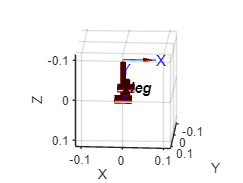

leg.plot([0,0,0], 'nobase', 'noshadow', 'notiles')
% 这条命令的作用是反转当前坐标轴（gca 表示获取当前坐标轴）的Z轴方向
set(gca, 'Zdir', 'reverse'); view(137,48);


transl( leg.fkine([0.2,0,0]) )

ans =    -0.0199    0.0980   -0.1000


transl( leg.fkine([0,0.2,0]) )

ans =     0.0000    0.1179   -0.0781


transl( leg.fkine([0,0,0.2]) )

ans =     0.0000    0.1199   -0.0980


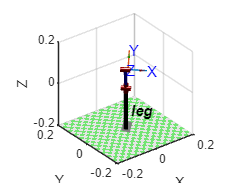

% 所需的轨迹由经点定义

xf = 50; xb = -xf;  y = 50; zu = 20; zd = 50;
path = [xf y zd; xb y zd; xb y zu; xf y zu; xf y zd] * 1e-3;

% TSEG (1xM) are the durations for each of the K segments
p = mstraj(path, [], [0, 3, 0.25, 0.5, 0.25]', path(1,:), 0.01, 0);

qcycle = leg.ikine( SE3(p), 'mask', [1 1 1 0 0 0] );

%leg.plot(qcycle, 'loop')
clf
leg.plot(qcycle,'delay', 0.02)

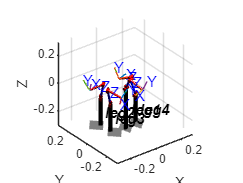


W = 0.1; L = 0.2;

legs(1) = SerialLink(leg, 'name', 'leg1');
legs(2) = SerialLink(leg, 'name', 'leg2', 'base', SE3(-L, 0, 0));
legs(3) = SerialLink(leg, 'name', 'leg3', 'base', SE3(-L, -W, 0) ...
*SE3.Rz(pi));
legs(4) = SerialLink(leg, 'name', 'leg4', 'base', SE3(0, -W, 0) ...
* SE3.Rz(pi));

clf
% k = 1;
% while 1
for k = 1:600
    %q = qleg(p,:);
    legs(1).plot( gait(qcycle, k, 0, false), 'workspace', [-0.3 0.3 -0.3 0.3 -0.3 0.3]);
    if k == 1, hold on; end
    legs(2).plot( gait(qcycle, k, 100, false) );
    legs(3).plot( gait(qcycle, k, 200, true) );
    legs(4).plot( gait(qcycle, k, 300, true) );
    drawnow
%    k = k+1;
end

A more polished version of this display is created by the script examples/walking.m